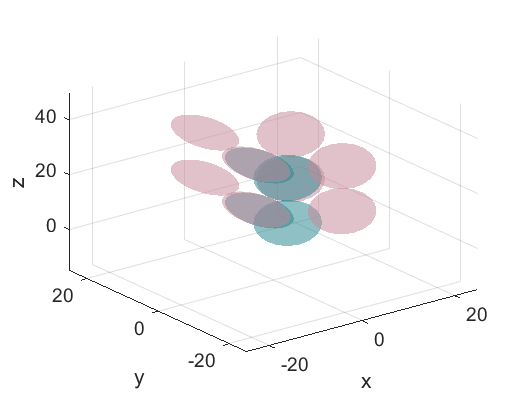

clear all
ax = axes('XLim',[-25 25],'YLim',[-25 25],'ZLim',[-15 50]);
view(3)

R11=6.80;
R31=3.96;
R12=6.71;
R32=6.90;
u32=[0.856;0.117;0.504];

[x1,y1,z1] = ellipsoid(3.42,0.473,4.01,R11,R11,R31,20);
[x2,y2,z2] = ellipsoid(7.69,-9.29,12.16,R11,R11,R31,20);
[x3,y3,z3] = ellipsoid(10.14,8.36,12.16,R11,R11,R31,20);

hold on

h(1)=surf(x1,y1,z1,'FaceColor',[36,133,142]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);

g(1)=surf(x2,y2,z2,'FaceColor',[200,137,153]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);

f(1)=surf(x3,y3,z3,'FaceColor',[200,137,153]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);


grid on
hold off


t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);
t4 = hgtransform('Parent',ax);

r1 = hgtransform('Parent',ax);
r2 = hgtransform('Parent',ax);
r3 = hgtransform('Parent',ax);
r4 = hgtransform('Parent',ax);

s1 = hgtransform('Parent',ax);
s2 = hgtransform('Parent',ax);
s3 = hgtransform('Parent',ax);
s4 = hgtransform('Parent',ax);

Rx = makehgtform('xrotate',7.8*pi/180);
Ry = makehgtform('yrotate',-59.7*pi/180);
Rz1 = makehgtform('zrotate',7.78*pi/180);
Rz = makehgtform('zrotate',pi);

Tz1 = makehgtform('translate',[0 0 8.22]);
Tr1 = makehgtform('translate',[3.42 0.473 4.01]);
Tr2 = makehgtform('translate',[7.69 -9.29 12.16]);
Tr3 = makehgtform('translate',[10.14 8.36 12.16]);

set(h,'Parent',t1);
set(g,'Parent',r1);
set(f,'Parent',s1);

h2 = copyobj(h,t2);
h3 = copyobj(h,t3);
h4 = copyobj(h,t4);

g2 = copyobj(g,r2);
g3 = copyobj(g,r3);
g4 = copyobj(g,r4);

f2 = copyobj(f,s2);
f3 = copyobj(f,s3);
f4 = copyobj(f,s4);

set(t1,'Matrix',Tr1*Rz1*Ry*Rz1/Tr1)
set(t2,'Matrix',Tz1*Rz*Tr1*Rz1*Ry*Rz1/Tr1)
set(t3,'Matrix',(Tz1*Rz)^2*Tr1*Rz1*Ry*Rz1/Tr1)
set(t4,'Matrix',(Tz1*Rz)^3*Tr1*Rz1*Ry*Rz1/Tr1)

set(r1,'Matrix',Tr2*Rz1*Ry*Rz1/Tr2)
set(r2,'Matrix',Tz1*Rz*Tr2*Rz1*Ry*Rz1/Tr2)
set(r3,'Matrix',(Tz1*Rz)^2*Tr2*Rz1*Ry*Rz1/Tr2)
set(r4,'Matrix',(Tz1*Rz)^3*Tr2*Rz1*Ry*Rz1/Tr2)

set(s1,'Matrix',Tr3*Rz1*Ry*Rz1/Tr3)
set(s2,'Matrix',Tz1*Rz*Tr3*Rz1*Ry*Rz1/Tr3)
set(s3,'Matrix',(Tz1*Rz)^2*Tr3*Rz1*Ry*Rz1/Tr3)
set(s4,'Matrix',(Tz1*Rz)^3*Tr3*Rz1*Ry*Rz1/Tr3)

xlabel('x'); ylabel('y'); zlabel('z')
drawnow

for i = 1:360
   camorbit(1,0,'data',[0 0 1])

   drawnow
end